# Modeling a serial-link robot manipulator

Copyright (C) 1993-2018, by Peter I. Corke, http://www.petercorke.com

A serial link manipulator comprises a series of links.  Each link is described by four Denavit-Hartenberg parameters.

Let's define a simple 2 link manipulator.  The first link is

L1 = Link('d', 0, 'a', 1, 'alpha', pi/2)

 
L1 = 
Revolute(std): theta=q, d=0, a=1, alpha=1.5708, offset=0


The Link object we created has a number of properties

L1.a

ans = 1

L1.d

ans = 0

and we determine that it is a revolute joint

L1.isrevolute

ans = logical
   1


For a given joint angle, say q=0.2 rad, we can determine the link transform matrix

L1.A(0.2)

 

ans = 
    0.9801         0    0.1987    0.9801
    0.1987         0   -0.9801    0.1987
         0         1         0         0
         0         0         0         1


The second link is

L2 = Link('d', 0, 'a', 1, 'alpha', 0)

 
L2 = 
Revolute(std): theta=q, d=0, a=1, alpha=0, offset=0


Now we need to join these into a serial-link robot manipulator

bot = SerialLink([L1 L2], 'name', 'my robot')

 
bot = 
 
my robot:: 2 axis, RR, stdDH, fastRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|     1.5708|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


The displayed robot object shows a lot of details.  It also has a number of properties such as the number of joints

bot.n

ans = 2

Given the joint angles q1 = 0.1 and q2 = 0.2 we can determine the pose of the robot's end-effector

bot.fkine([0.1 0.2])

 

ans = 
    0.9752   -0.1977    0.0998      1.97
    0.0978   -0.0198   -0.9950    0.1977
    0.1987    0.9801         0    0.1987
         0         0         0         1


which is referred to as the forward kinematics of the robot.  This, and the inverse kinematics are covered in separate demos.

Finally we can draw a stick figure of our robot

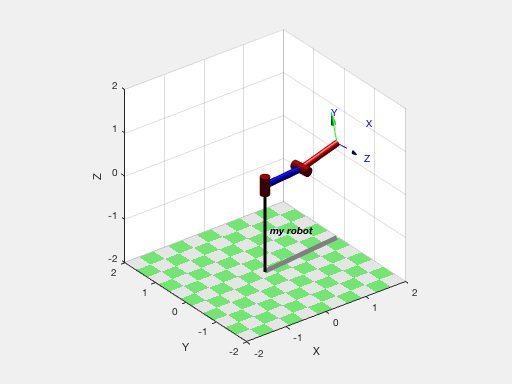

bot.plot([0.1 0.2])